# MXB201 Solutions 3

## Theory

T1.  Let $A \in \mathbb{R}^{m \times n}$ have full column rank.  We know that the orthogonal projector onto $A$'s column space is given by $P = A(A^TA)^{-1} A^T$.  Now, substitute $A = QR$ into $P$, where $Q$ and $R$ form the QR decomposition of $A$.  Show that the orthogonal projector reduces simply to $P = QQ^T$.


$$P = (QR)\left((QR)^T(QR)\right)^{-1}(QR)^T$$



$$P = QR(R^T Q^T Q R)^{-1} R^TQ^T$$



$$P = QR(R^T R)^{-1}R^TQ^T$$



$$P = QRR^{-1}R^{-T}R^TQ^T$$



$$P = QQ^T$$


## Practice

P1.

(i) Use the Gram-Schmidt process to find orthonormal bases for the four fundamental subspaces of the matrix $A$ below.  This is the matrix from Exercises 2 P2.

A = sym([3 1 -3 ; 3 2 0 ; 2 1 -1])

$$A = \left(\begin{array}{ccc} 3 & 1 & -3\\ 3 & 2 & 0\\ 2 & 1 & -1 \end{array}\right)$$

We'll get MATLAB to calculate bases for the four fundamental subspaces.

RS = colspace(A'), CS = colspace(A), NS = null(A), LNS = null(A')

$$RS = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -2 & 3 \end{array}\right)$$

$$CS = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

$$NS = \left(\begin{array}{c} 2\\ -3\\ 1 \end{array}\right)$$

$$LNS = \left(\begin{array}{c} -\frac{1}{3}\\ -\frac{1}{3}\\ 1 \end{array}\right)$$

Now we perform the Gram-Schmidt process on these sets of vectors.  In fact, the two null spaces have only one vector, so they just need normalising.  We'll do them first.

NS_ONB = NS / norm(NS)

$$NS\_ONB = \left(\begin{array}{c} \frac{\sqrt{14}}{7}\\ -\frac{3\,\sqrt{14}}{14}\\ \frac{\sqrt{14}}{14} \end{array}\right)$$

LNS_ONB = LNS / norm(LNS)

$$LNS\_ONB = \left(\begin{array}{c} -\frac{\sqrt{11}}{11}\\ -\frac{\sqrt{11}}{11}\\ \frac{3\,\sqrt{11}}{11} \end{array}\right)$$

Now for the row and column spaces.  Here we do need to apply the proper Gram-Schmidt process.  We'll do row space first.

v1 = RS(:,1)  % first vector in basis

$$v1 = \left(\begin{array}{c} 1\\ 0\\ -2 \end{array}\right)$$

q1 = v1 / norm(v1) % normalise it

$$q1 = \left(\begin{array}{c} \frac{\sqrt{5}}{5}\\ 0\\ -\frac{2\,\sqrt{5}}{5} \end{array}\right)$$

w2 = RS(:,2) % second vector in basis

$$w2 = \left(\begin{array}{c} 0\\ 1\\ 3 \end{array}\right)$$

v2 = w2 - dot(w2, q1) * q1  % subtract off its projection onto q1

$$v2 = \left(\begin{array}{c} \frac{6}{5}\\ 1\\ \frac{3}{5} \end{array}\right)$$

q2 = v2 / norm(v2)  % normalise it

$$q2 = \left(\begin{array}{c} \frac{3\,\sqrt{5}\,\sqrt{14}}{35}\\ \frac{\sqrt{5}\,\sqrt{14}}{14}\\ \frac{3\,\sqrt{5}\,\sqrt{14}}{70} \end{array}\right)$$

RS_ONB = [q1 q2]  % augment the orthonormal vectors 

$$RS\_ONB = \left(\begin{array}{cc} \frac{\sqrt{5}}{5} & \frac{3\,\sqrt{5}\,\sqrt{14}}{35}\\ 0 & \frac{\sqrt{5}\,\sqrt{14}}{14}\\ -\frac{2\,\sqrt{5}}{5} & \frac{3\,\sqrt{5}\,\sqrt{14}}{70} \end{array}\right)$$

Now column space.

v1 = CS(:,1)  % first vector in basis

$$v1 = \left(\begin{array}{c} 1\\ 0\\ \frac{1}{3} \end{array}\right)$$

q1 = v1 / norm(v1) % normalise it

$$q1 = \left(\begin{array}{c} \frac{3\,\sqrt{10}}{10}\\ 0\\ \frac{\sqrt{10}}{10} \end{array}\right)$$

w2 = CS(:,2) % second vector in basis

$$w2 = \left(\begin{array}{c} 0\\ 1\\ \frac{1}{3} \end{array}\right)$$

v2 = w2 - dot(w2, q1) * q1  % subtract off its projection onto q1

$$v2 = \left(\begin{array}{c} -\frac{1}{10}\\ 1\\ \frac{3}{10} \end{array}\right)$$

q2 = v2 / norm(v2)  % normalise it

$$q2 = \left(\begin{array}{c} -\frac{\sqrt{10}\,\sqrt{11}}{110}\\ \frac{\sqrt{10}\,\sqrt{11}}{11}\\ \frac{3\,\sqrt{10}\,\sqrt{11}}{110} \end{array}\right)$$

CS_ONB = [q1 q2]  % augment the orthonormal vectors 

$$CS\_ONB = \left(\begin{array}{cc} \frac{3\,\sqrt{10}}{10} & -\frac{\sqrt{10}\,\sqrt{11}}{110}\\ 0 & \frac{\sqrt{10}\,\sqrt{11}}{11}\\ \frac{\sqrt{10}}{10} & \frac{3\,\sqrt{10}\,\sqrt{11}}{110} \end{array}\right)$$

(ii) Use these orthonormal bases to calculate orthogonal projectors onto the four fundamental subspaces, and confirm they come out the same as those you found in Exercises 2 P2.

P_RS = RS_ONB * RS_ONB'

$$P\_RS = \left(\begin{array}{ccc} \frac{5}{7} & \frac{3}{7} & -\frac{1}{7}\\ \frac{3}{7} & \frac{5}{14} & \frac{3}{14}\\ -\frac{1}{7} & \frac{3}{14} & \frac{13}{14} \end{array}\right)$$

P_CS = CS_ONB * CS_ONB'

$$P\_CS = \left(\begin{array}{ccc} \frac{10}{11} & -\frac{1}{11} & \frac{3}{11}\\ -\frac{1}{11} & \frac{10}{11} & \frac{3}{11}\\ \frac{3}{11} & \frac{3}{11} & \frac{2}{11} \end{array}\right)$$

P_NS = NS_ONB * NS_ONB'

$$P\_NS = \left(\begin{array}{ccc} \frac{2}{7} & -\frac{3}{7} & \frac{1}{7}\\ -\frac{3}{7} & \frac{9}{14} & -\frac{3}{14}\\ \frac{1}{7} & -\frac{3}{14} & \frac{1}{14} \end{array}\right)$$

P_LNS = LNS_ONB * LNS_ONB'

$$P\_LNS = \left(\begin{array}{ccc} \frac{1}{11} & \frac{1}{11} & -\frac{3}{11}\\ \frac{1}{11} & \frac{1}{11} & -\frac{3}{11}\\ -\frac{3}{11} & -\frac{3}{11} & \frac{9}{11} \end{array}\right)$$

(iii) Assemble the bases for the row space and null space into a complete orthonormal basis for $R^3$.

ONB1 = [RS_ONB NS_ONB]

$$ONB1 = \left(\begin{array}{ccc} \frac{\sqrt{5}}{5} & \frac{3\,\sqrt{5}\,\sqrt{14}}{35} & \frac{\sqrt{14}}{7}\\ 0 & \frac{\sqrt{5}\,\sqrt{14}}{14} & -\frac{3\,\sqrt{14}}{14}\\ -\frac{2\,\sqrt{5}}{5} & \frac{3\,\sqrt{5}\,\sqrt{14}}{70} & \frac{\sqrt{14}}{14} \end{array}\right)$$

ONB1'*ONB1  % confirm full ONB

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

(iv) Assemble the bases for the column space and left null space into a complete orthonormal basis for $R^3$.

ONB2 = [CS_ONB LNS_ONB]

$$ONB2 = \left(\begin{array}{ccc} \frac{3\,\sqrt{10}}{10} & -\frac{\sqrt{10}\,\sqrt{11}}{110} & -\frac{\sqrt{11}}{11}\\ 0 & \frac{\sqrt{10}\,\sqrt{11}}{11} & -\frac{\sqrt{11}}{11}\\ \frac{\sqrt{10}}{10} & \frac{3\,\sqrt{10}\,\sqrt{11}}{110} & \frac{3\,\sqrt{11}}{11} \end{array}\right)$$

ONB2'*ONB2 % confirm full ONB

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

P2. Anton's Exercise Set 6.3.

Questions 1, 5, 7, 11, 15, 17, 19, 21, 23, 25, 27, 29, 31, 33, 35, 49

## Exploration

E1.  Suppose you have a matrix $A$ of full column rank, and you apply the Gram-Schmidt process as usual to generate the matrix $Q$, which has the same column space as $A$ but with orthonormal columns.  Later, you realise you really want the QR decomposition of $A$.  Alas, you forgot to record your working when applying the Gram-Schmidt procss!  Is the situation hopless?  Or is there a way to recover the matrix $R$ you need for the QR decomposition from $A$ and $Q$ without having to start the process all over again?  If you think you have a method, experiment with a small, made-up example to see if it works.

If $A = QR$ then apply $Q^T$ on  both sides to see that $Q^T A = Q^TQR$, or since $Q^TQ = I$, simply $Q^TA = R$.

A = sym(round(10*rand(4,3)-5)), [Q,~] = qr(A)

$$A = \left(\begin{array}{ccc} -2 & -3 & 4\\ 3 & -2 & 1\\ -1 & -4 & 0\\ 4 & -4 & -4 \end{array}\right)$$

$$Q = \left(\begin{array}{cccc} -\frac{\sqrt{30}}{15} & -\frac{19\,\sqrt{5}\,\sqrt{201}}{1005} & \frac{401\,\sqrt{402}\,\sqrt{6947}}{1396347} & \frac{76\,\sqrt{20841}}{20841}\\ \frac{\sqrt{30}}{10} & -\frac{4\,\sqrt{5}\,\sqrt{201}}{1005} & \frac{1195\,\sqrt{402}\,\sqrt{6947}}{2792694} & -\frac{20\,\sqrt{20841}}{6947}\\ -\frac{\sqrt{30}}{30} & -\frac{22\,\sqrt{5}\,\sqrt{201}}{1005} & -\frac{563\,\sqrt{402}\,\sqrt{6947}}{2792694} & -\frac{88\,\sqrt{20841}}{20841}\\ \frac{2\,\sqrt{30}}{15} & -\frac{4\,\sqrt{5}\,\sqrt{201}}{335} & -\frac{106\,\sqrt{402}\,\sqrt{6947}}{465449} & \frac{61\,\sqrt{20841}}{20841} \end{array}\right)$$

R = Q'*A

$$R = \left(\begin{array}{ccc} \sqrt{30} & -\frac{2\,\sqrt{30}}{5} & -\frac{7\,\sqrt{30}}{10}\\ 0 & \frac{\sqrt{5}\,\sqrt{201}}{5} & -\frac{32\,\sqrt{5}\,\sqrt{201}}{1005}\\ 0 & 0 & \frac{\sqrt{402}\,\sqrt{6947}}{402}\\ 0 & 0 & 0 \end{array}\right)$$

isequal(A, Q*R)

ans = logical
   1

Yes, this works.  Computing $R$ this way is a reminder that for an orthonormal basis, any vector in the space can be written $v = (v \cdot q_1) q_1 + (v \cdot q_2) q_2 + (v \cdot q_3) q_3$.  Computing $Q^T A$ is simply calculating these dot products for each column of $A$.

E2.  Let $A$ be any random $5 \times 3$ matrix.  We'll use floating point arithmetic:

A = rand(5,3)

A =     0.8530    0.0760    0.4173
    0.6221    0.2399    0.0497
    0.3510    0.1233    0.9027
    0.5132    0.1839    0.9448
    0.4018    0.2400    0.4909


We know to perform a QR decomposition in MATLAB we use the syntax:

[Q,R] = qr(A, 0)  % with comma zero

Q =    -0.6616    0.6944    0.0702
   -0.4824   -0.3259    0.6206
   -0.2722   -0.1296   -0.6114
   -0.3980   -0.2056   -0.4841
   -0.3116   -0.5938    0.0425


R =    -1.2894   -0.3475   -1.0747
         0   -0.2217   -0.3291
         0         0   -0.9283


What then, does the command

[Q,R] = qr(A)  % no comma zero

Q =    -0.6616    0.6944    0.0702   -0.0532    0.2692
   -0.4824   -0.3259    0.6206   -0.0698   -0.5206
   -0.2722   -0.1296   -0.6114   -0.6644   -0.3064
   -0.3980   -0.2056   -0.4841    0.7304   -0.1774
   -0.3116   -0.5938    0.0425   -0.1318    0.7288


R =    -1.2894   -0.3475   -1.0747
         0   -0.2217   -0.3291
         0         0   -0.9283
         0         0         0
         0         0         0


produce?  In particular, what is the meaning of the "extra" columns in $Q$?  Test any ideas you come up with to see if you're correct.

We might think to check that the matrix $Q$ still has orthonormal columns.

Q'*Q

ans =     1.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000    1.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000    1.0000


Indeed it does.  So the additional vectors in $Q$ are orthogonal not just to each other, but to all the vectors that came before.  Hence, these extra vectors must belong to the orthogonal complement of the column space of $A$, i.e., to the left null space of $A$.  Testing our theory:

LNS = Q(:, 4:5)

LNS =    -0.0532    0.2692
   -0.0698   -0.5206
   -0.6644   -0.3064
    0.7304   -0.1774
   -0.1318    0.7288


A' * LNS  % should be zero if our theory is correct

ans = 	1.0e+-15 *

    0.0278   -0.0555
    0.0139   -0.0278
    0.1943    0.1110


So the "full" QR decomposition generates an orthonormal basis for all of $\mathbb{R}^m$.  Only the first $n$ columns are a basis for the column space of $A$.  The remaining columns are a basis for the left null space.

## Application

In this section we will use *floating point arithmetic*, since the problems are of a sufficient size to make symbolic arithmetic inefficient.

### A1 Function approximation

Suppose we want to approximate some function $f(t)$ over the interval $[a,b]$ by a polynomial of degree $n$, $P(t) = c_0 + c_1 t + \ldots + c_nt^n$.  What polynomial should we choose to get the "best possible" accuracy over the entire inverval?

One approach we might think of is to sample the function $f$ at $m$ uniformly-spaced points $t_i,\ i=1,\ldots, m$ over the interval $[a,b]$ and find the least squares polynomial through the data points we sampled.  That is, we form the overdetermined linear system $Ac = b$ given by

$\left\lbrack \begin{array}{ccccc}
1 & t_1  & {t_1 }^2  & \cdots  & {t_1 }^n \\
1 & t_2  & {t_2 }^2  & \cdots  & {t_2 }^n \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & t_m  & {t_m }^2  & \cdots  & {t_m }^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_0 \\
c_1 \\
\vdots \\
c_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f\left(t_1 \right)\\
f\left(t_2 \right)\\
\vdots \\
f\left(t_m \right)
\end{array}\right\rbrack$,      $m \gg n$  (so $A$ is a tall matrix)

Let's try it out on an example.  Let $f(t) = e^t$ over the interval $[0,1]$, and we'll fit a polynomial of degree $n = 12$.  Suppose we sample $f$ at $m = 50$ uniformly-spaced points on $[0,1]$.

(i) Generate the coefficient matrix $A$ and right hand side vector $b$.

clear
m = 50; n = 12;
t = linspace(0,1,m)';
A = t.^(0:n)

A =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000    0.0204    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0408    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0612    0.0037    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0816    0.0067    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1020    0.0104    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1224    0.0150    0.0018    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.000

b = exp(t)

b =     1.0000
    1.0206
    1.0417
    1.0631
    1.0851
    1.1074
    1.1303
    1.1536
    1.1773
    1.2016


(ii) Set up and solve the normal equations $A^TAc = A^T b$ to find the solution vector of coefficients $c_0$ to $c_{12}$.  Let's call the resulting polynomial ${P}^{(ii)}(t)$.

c = (A'*A) \ (A'*b)

c =     1.0000
    1.0000
    0.4998
    0.1694
    0.0162
    0.1480
   -0.4882
    1.1362
   -1.7663
    1.8204


(iii) Find the QR decomposition of $A$ (use MATLAB's `qr` function).

[Q,R] = qr(A, 0)

Q =    -0.1414   -0.2401   -0.2978   -0.3318    0.3473    0.3473    0.3346   -0.3122   -0.2828    0.2493    0.2140    0.1790   -0.1461
   -0.1414   -0.2303   -0.2613   -0.2506    0.2055    0.1347    0.0478    0.0446    0.1328   -0.2086   -0.2664   -0.3033    0.3191
   -0.1414   -0.2205   -0.2264   -0.1778    0.0904   -0.0159   -0.1195    0.2007    0.2453   -0.2467   -0.2063   -0.1325    0.0380
   -0.1414   -0.2107   -0.1930   -0.1131   -0.0009   -0.1151   -0.1978    0.2273    0.1967   -0.1152   -0.0045    0.1078   -0.1954
   -0.1414   -0.2009   -0.1611   -0.0561   -0.0707   -0.1723   -0.2127    0.1785    0.0825    0.0419    0.1529    0.2146   -0.2086
   -0.1414   -0.1911   -0.1307   -0.0066   -0.1215   -0.1961   -0.1851    0.0941   -0.0373    0.1536    0.2068    0.1760   -0.0748
   -0.1414   -0.1813   -0.1018    0.0360   -0.1556   -0.1941   -0.1322    0.0023   -0.1293    0.1965    0.1666    0.0551    0.0835
   -0.1414   -0.1715   -0.0745    0.0719   -0.1752   -0.1730   -0.0673   -0.078

R =    -7.0711   -3.5355   -2.3811   -1.8038   -1.4576   -1.2269   -1.0621   -0.9386   -0.8426   -0.7658   -0.7031   -0.6508   -0.6066
         0    2.0825    2.0825    1.8868    1.6911    1.5235    1.3838    1.2675    1.1699    1.0871    1.0162    0.9549    0.9015
         0         0   -0.5482   -0.8223   -0.9445   -0.9906   -0.9983   -0.9865   -0.9649   -0.9387   -0.9107   -0.8825   -0.8550
         0         0         0    0.1416    0.2832    0.3948    0.4765    0.5342    0.5741    0.6008    0.6181    0.6285    0.6338
         0         0         0         0    0.0363    0.0907    0.1489    0.2037    0.2521    0.2937    0.3286    0.3577    0.3816
         0         0         0         0         0   -0.0093   -0.0278   -0.0525   -0.0803   -0.1089   -0.1370   -0.1635   -0.1881
         0         0         0         0         0         0    0.0024    0.0082    0.0176    0.0298    0.0440    0.0595    0.0756
         0         0         0         0         0         0         0    0.000

(iv) Solve the system $Rc = Q^T b$ to find the solution vector of coefficients; use a different symbol (say, capital `C)` in MATLAB so you don't overwrite your solution from (ii).  Let's call the resulting polynomial ${P}^{(iv)}(t)$.

C = R \ (Q'*b)

C =     1.0000
    1.0000
    0.5000
    0.1667
    0.0417
    0.0083
    0.0014
    0.0002
    0.0000
    0.0000


(v) Mathematically, your answers for (ii) and (iv) should be identical.  But are they?  If not, which set of coefficients do you trust more?  How do you judge which are the more reliable?

[c'; C']

ans =     1.0000    1.0000    0.4998    0.1694    0.0162    0.1480   -0.4882    1.1362   -1.7663    1.8204   -1.1931    0.4502   -0.0745
    1.0000    1.0000    0.5000    0.1667    0.0417    0.0083    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000


I am highly dubious of the large and negative coefficients in lower case $c$ (from part (ii) using the normal equations).  I also note that MATLAB warned me that the results of the linear solve in (ii) may be inaccurate.

As a means of validation, I don't expect this least squares polynomial should be radically different from the Taylor polynomial centred at $t = 0$, which has coefficients

1./factorial(0:n)

ans =     1.0000    1.0000    0.5000    0.1667    0.0417    0.0083    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000


These seem to closely match the coefficients in upper case $C$ (from part (iv) using the QR decomposition).  So I think the coefficients from (iv) are more reliable.

(vi) Produce a plot of $e^t$, ${P}^{(ii)}(t)$ and ${P}^{(iv)}(t)$over the interval $[0,1]$ on the same axes.  Can you tell them apart?

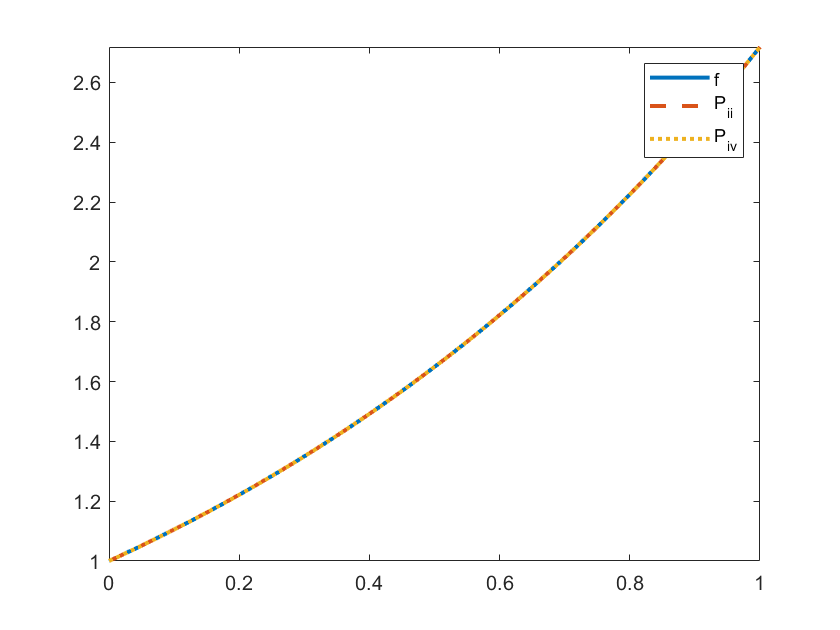

P_ii = @(t) polyval(flipud(c), t);
P_iv = @(t) polyval(flipud(C), t);
figure
fplot(@exp, [0,1], 'LineWidth', 2, 'DisplayName', 'f')
hold on
fplot(P_ii, [0,1], '--', 'LineWidth', 2, 'DisplayName', 'P_{ii}')
fplot(P_iv, [0,1], ':', 'LineWidth', 2, 'DisplayName', 'P_{iv}')
legend

Both polynomials seem visually indistinguishable from $f$ over $[0,1]$.

(vii) Now let's try using  ${P}^{(ii)}(t)$ and ${P}^{(iv)}(t)$for *extrapolation*.  Produce a plot of $e^t$, ${P}^{(ii)}(t)$ and ${P}^{(iv)}(t)$over the interval $[0,2]$ on the same axes.  Can you tell them apart?

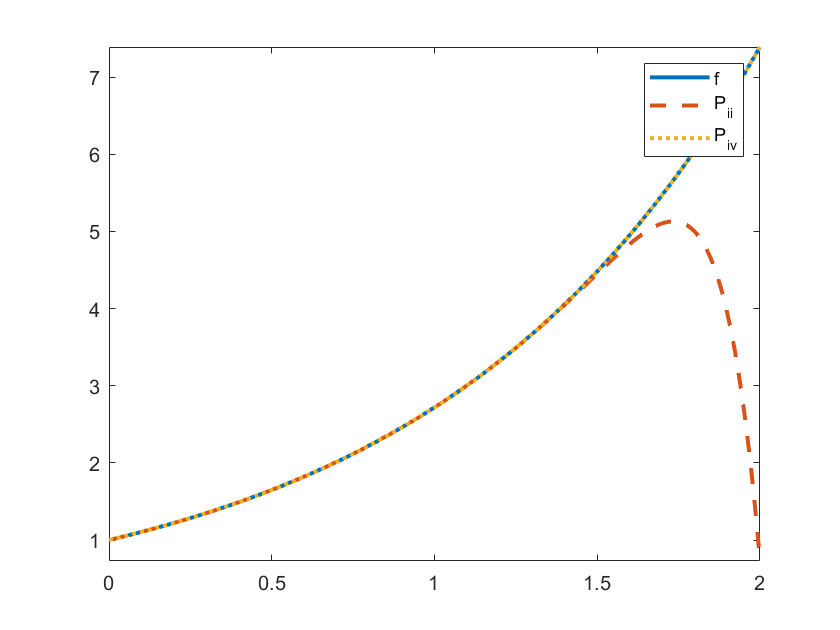

P_ii = @(t) polyval(flipud(c), t);
P_iv = @(t) polyval(flipud(C), t);
figure
fplot(@exp, [0,2], 'LineWidth', 2, 'DisplayName', 'f')
hold on
fplot(P_ii, [0,2], '--', 'LineWidth', 2, 'DisplayName', 'P_{ii}')
fplot(P_iv, [0,2], ':', 'LineWidth', 2, 'DisplayName', 'P_{iv}')
legend

Oh, yes, now I can tell them apart.  $P_{ii}$ fails badly after around $t = 1.5$ while $P_{iv}$ is still visually indistinguishable from $f$ over $[0,2]$.

## Software

### S1. QR factorisation

Write a MATLAB function `QR` (capitals, to distinguish it from MATLAB's inbuilt `qr` function) that takes as input an $m\times n$ matrix $A$ and performs the Gram-Schmidt process to return matrices $Q$ and $R$ such that $A = QR$.  The function should:

- output an **error **message if $A$ does not have full column rank.

Test your function out on various examples to check it works correctly.